# ** White Gaussian Noise Generator**

% ************************************************************************
% Author: CONG LI
% Date Created: 2023
%
% This script is part of a course project for 
% Communication Systems: Theory and Measurement M
% at University of Bologna.
% ************************************************************************
close all % close all plots
clear all % clear all variables
clc % clear the screen

**Generation of the sinusoid and plot**

The following code segment generated sinusoidal signal with parameters defined below and plotting.

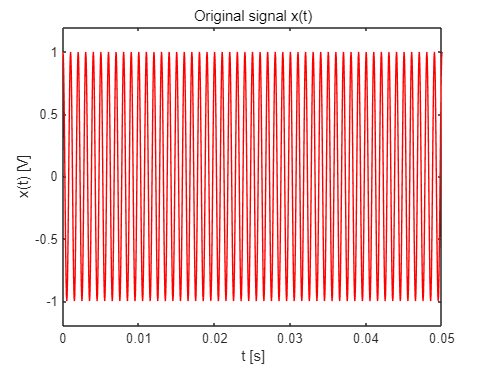

%% generation of the sinusiod and plot
A=1; % Amplitude of the sinusoid  [V] 
f0=1000; % frequency of the sinusoid 
fs=20000; % sampling frequency 
duration=0.05; % singal duration in seconds
[t,x,N]=SinusoidalSource2023(A,f0,duration,fs); % generation of the singal

plot(t,x,'r')
xlabel('t [s]')
ylabel('x(t) [V]')
title('Original signal x(t)')
axis([min(t) max(t) 1.2*min(x) 1.2*max(x)])

The original signal is a sinusoidal waveform with an Amplitude of 1V, frequency of 1000hz and duration is 0.05seconds.

signal_power=0.5*A^2;
fprintf('sinusoid power [V^2]=%f' , signal_power)

sinusoid power [V^2]=0.500000

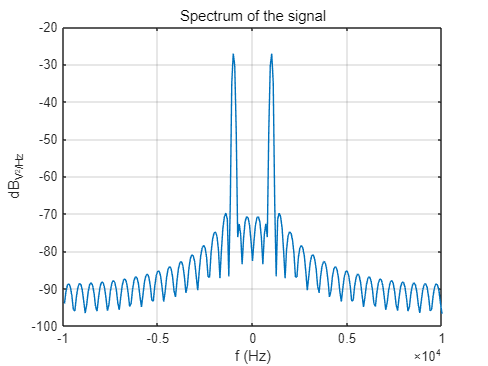

figure
PlotSpectrum(x,fs);
title('Spectrum of the signal');

The picture above shows the the spectrum of the signal, which represents the power distribution in frequency domain. The two peaks are more than -30dB and symmetrical around the 0 frequency at 1kHz and -1kHz.

**Noise Generation**

The following code segment generated Gaussian noise signal with parameter defined below and added to the original sinusoidal signal. The power of noise and SNR is calculated. Finally, the original signal and the noisy signal are campared. The following expression is probability density function (PDF) of a Gaussian distribution is with a zero mean and variance σ^2.

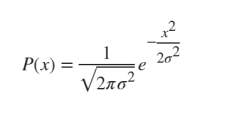

%% Noise generation 
sigma=0.6; % std deviation of the noise. The noise power is sigma ^2 [v^2]
noise=sigma*randn(1,N); % generation the noise 
fprintf('Noise power[V^2]=%f', sigma^2)

Noise power[V^2]=0.360000

x_noisy=x+noise; % add Gussian noise to sinusoid 

signal_to_noise_ratio_dB=10*log10(signal_power/(sigma^2));
fprintf('SNR [dB]=%f',signal_to_noise_ratio_dB)

SNR [dB]=1.426675

figure
plot(t,x_noisy,'k')
hold on 
plot(t,x,'r')
legend('x(t)+noise','x(t)')
title('Signals');

xlim([0.0043 0.0456])
ylim([-2.32 2.64])
 
xt = findobj(gcf, "DisplayName", "x(t)")

xt =   Line (x(t)) - 属性:

              Color: [1 0 0]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [0 5.0000e-05 1.0000e-04 1.5000e-04 2.0000e-04 2.5000e-04 3.0000e-04 3.5000e-04 4.0000e-04 4.5000e-04 5.0000e-04 5.5000e-04 6.0000e-04 6.5000e-04 7.0000e-04 7.5000e-04 8.0000e-04 8.5000e-04 9.0000e-04 9.5000e-04 … ] (1×1001 double)
              YData: [1 0.9511 0.8090 0.5878 0.3090 6.1232e-17 -0.3090 -0.5878 -0.8090 -0.9511 -1 -0.9511 -0.8090 -0.5878 -0.3090 -1.8370e-16 0.3090 0.5878 0.8090 0.9511 1 0.9511 0.8090 0.5878 0.3090 3.0616e-16 -0.3090 -0.5878 -0.8090 … ] (1×1001 double)

  显示 所有属性


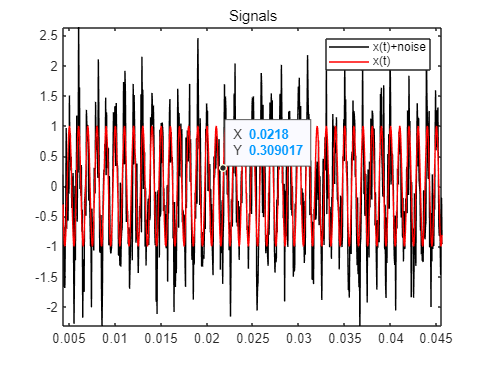

datatip(xt,0.0218,0.309);

The original signal and noisy signal are plotted in one picture. In general, this picture  shows that noisy signal amplitude is between 1.6 and 0.4 which is the amplitude plus  sigma and amplitude minus sigma, the noise only affects amplitude, because of the  AWGN feture: Additive, White, zero mean, Gaussian, stationary and uncorrelated.

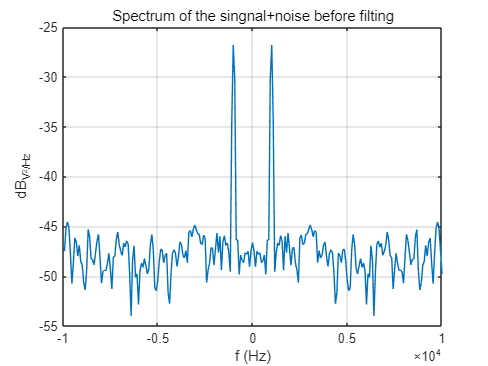

figure 
PlotSpectrum(x_noisy,fs);
title('Spectrum of the singnal+noise before filting');

The picture shows above illustrated the spectrum of the signal with noise. Comparing to the spectrum of the signal without noise, it can be found that the power is uniformly distributed in the spectrum except at 1000 Hz and -1000 Hz. The power at each single frequency is a random value.

**FIR Filter**

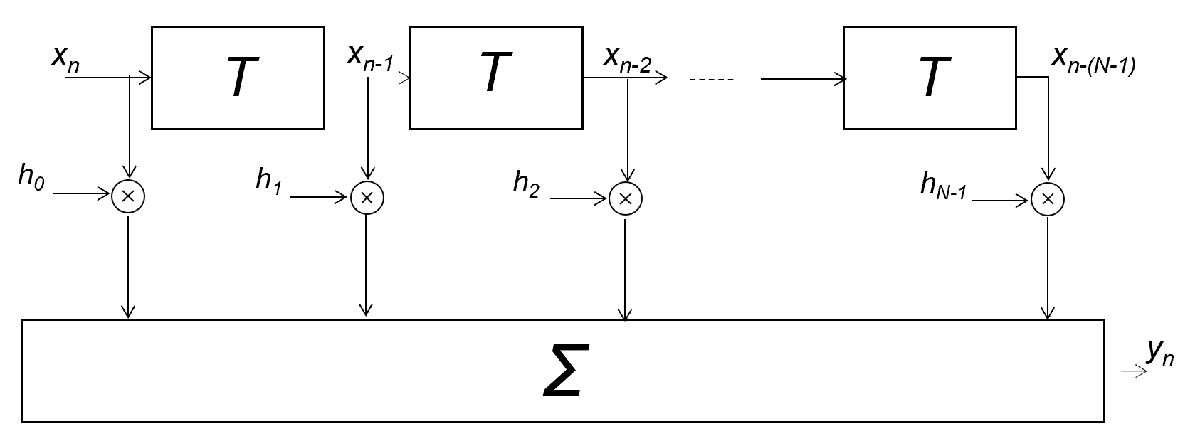

This is a digital filter used to process signals by convolution operation. The input signal is convolved  with filter coefficient.

Nf=400; % Number of FIR filter taps

**Low pass filter design **

The following code segment generated a low pass filter with a 3dB cut off frequency Fpass is set to  2000 hz. 

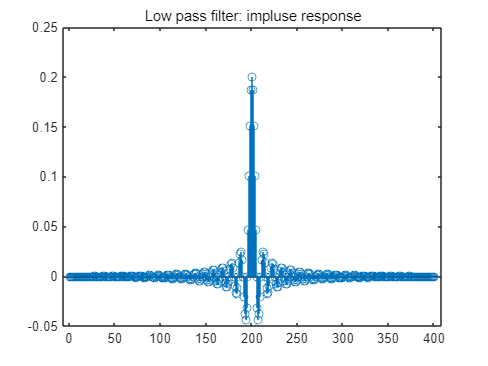

%% *Low pass filter design *
Fpass=2000; % 3dB cut frequency
h_lowpass=fir1(Nf, Fpass/(0.5*fs)); % filter design 

%% *Filter impluse response and frequency respond (transfer function)*
stem(h_lowpass) %filter taps (coefficients), that is ,filter impluse resopnse 
title('Low pass filter: impluse response')

This picture shows the impulse response of low pass filter, in time domain, it is a sinc  function.

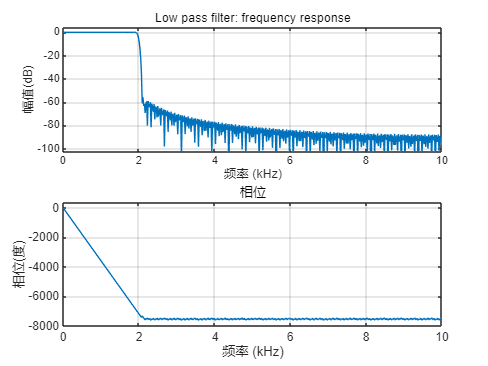

freqz(h_lowpass,1,[],fs); % plot the frequency response
title('Low pass filter: frequency response')

**Passband filter design**

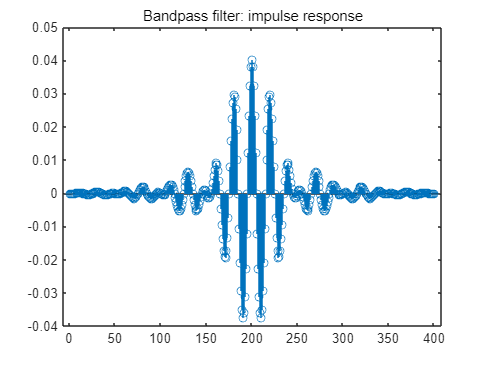

%% *Passband filter design*
Fpass1=800; % low cut frequency of the filter 
Fpass2=1200; % hign cut frequenct of the filter 
h_bandpass=fir1(Nf, [Fpass1/(0.5*fs) Fpass2/(0.5*fs)],'bandpass');% filer design 

%% *filter impluse response and frequency response (transfer function)*
stem(h_bandpass) % filter taps (coefficients), that is, filter impulse response 
title('Bandpass filter: impulse response')

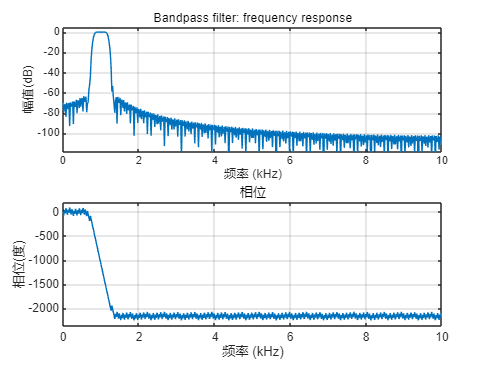

freqz(h_bandpass,1,[],fs); %plot the frequency resionse
title('Bandpass filter: frequency response')

By replacing the low pass filter with a bandpass filter, it can be concluded that in the  pass band the signal will pass, and signals below pass band or above will be  truncated. Similar to low pass filter the effect of the filter on phase of signals is also  linear.

**Filtering**

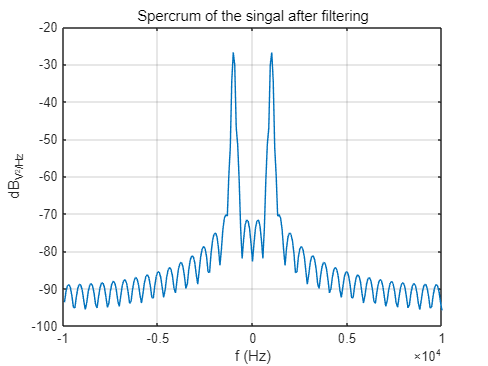

%% *Filtering*
y=conv(x_noisy,h_bandpass,'same'); % filter the singal with the bandpass filter
%y=conv(x_noise,h_lowpass,'same'); % filter the singal with the lowpass filter

%% *Plots*
figure 
PlotSpectrum(y,fs);
title('Spercrum of the singal after filtering');

It can be concluded that after passing the filter, most of the signal energy is  concentrated in the passband, and energy outside the passband is suppressed by  filter.

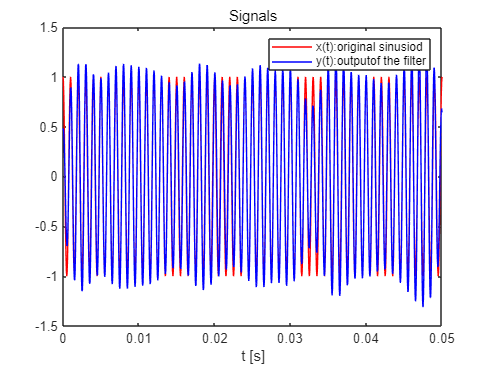

figure
plot(t,x,'r')

hold on 
plot(t,y,'b')
xlabel('t [s]')
legend('x(t):original sinusiod','y(t):outputof the filter')
title('Signals');

Comparing the signal passing through the filter and the original signal, their waveform  are basically similar and do not affect the extraction of information.

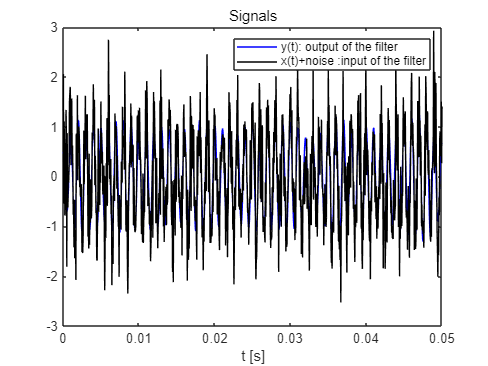

figure 
plot(t,y,'b')
hold on 
plot(t,x_noisy,'k')
xlabel('t [s]')
legend('y(t): output of the filter','x(t)+noise :input of the filter')
title('Signals')

Filters can effectively filter out clutter and improve signal quality.

**the outputs of the lowpass filte**

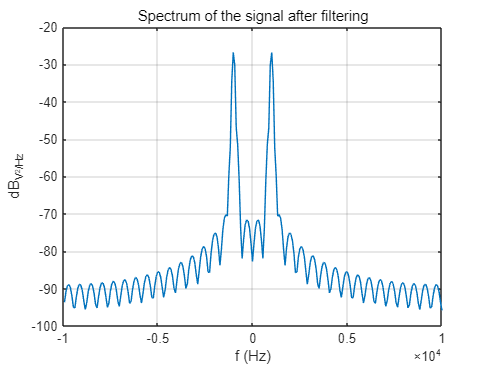

figure
PlotSpectrum(y,fs);
title('Spectrum of the signal after filtering')

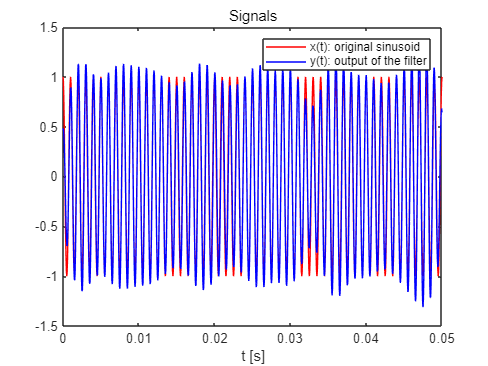

figure
plot(t,x,"r")
hold on
plot(t,y,'b')
xlabel('t [s]')
legend ('x(t): original sinusoid','y(t): output of the filter')
title('Signals');

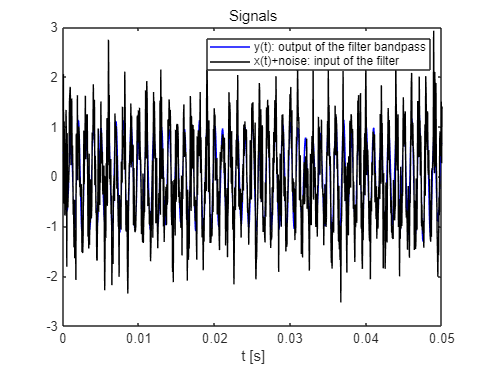

figure
plot(t,y,'b')
hold on
plot(t,x_noisy,'k')
xlabel('t [s]')
legend ('y(t): output of the filter bandpass','x(t)+noise: input of the filter')
title('Signals');

**Compare the outputs for different powers of the sine wave**

** increase the standard deviation**

**For sine wave, choose a frequency that does not fall within  the passband of the filter and observe the outputs. **